This section describes the method we used to get the vehicle parameters (namely *accelerationTable,decelertionTable *and* corneringVelocityTable*) from the simulink model given. This method can be termed as reverse engineering. For optimization we always require maximum velocity possible at a given instant, maximum acceleration and maximum deceleration possible  for a given velocity.

## Generating *accelerationTable*

The *accelerationTable* is the table of velocity data sites and corresponding possible maximum accelerations. To get this data we first specify a straight line path for the vehicle to traverse. The velocity input to the vehicle is substantially high (full throttle open), which allows vehicle to move with maximum possible velocity starting from rest.

- Following below is the script generating straight line path and specifying very high velocity.

%%The track points are straight line along X axis up to 15 km
L=15000;  %%Length of straight path along X-axis

x=0:0.4:L;
x=x';
n=size(x,1);
y=3.1250*ones(n,1);
pathPoints=[x y];

velocities=1000*ones(n,1);
splineParams=linspace(0,1,n);

%%Run the simulink model to get the data (Commented out as simulation takes lot of time)
% sim('controllerReference_accelerationTest.slx')

- Once we run the simulink model the vehicle data is stored in the file *fullThrottleResults.mat. *We use this file to further modify the obtained data. The following script proceses the data, smoothens it and removes outliers.

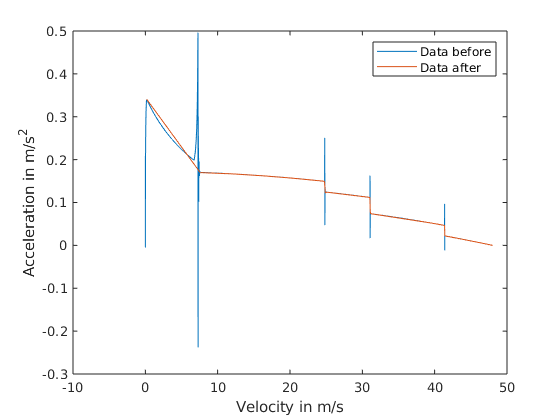

%%Load the file generated from simulink model
%%'ControllerReference_accelerationTest.slx'

load('fullThrottleResults.mat');

%%Read the acceleration and velocity data fom the simulink generated file
acc=results.VehFdbk.Body.ax.Data;
vel=results.VehFdbk.Body.Xdot.Data;

%%Plot the data before filtering
plot(vel,acc)
xlabel("Velocity in m/s")
ylabel("Acceleration in m/s^2")
hold on

%%Smoothing the  data using Savitzky-Golay filter
acc=smooth(acc,20,'sgolay',2);

%%Remove outliers
abs_diff=abs(diff(acc)./diff(vel));
[ref_abs_diff,TF]=rmoutliers(abs_diff,'percentile',[5 100]);

indices=find(TF);

%plot(vel(indices),acc(indices))

velRefined=vel(indices);
accRefined=acc(indices);


%%gear shift indices
diffAcc=abs(diff(accRefined));

meanDiffAcc=mean(diffAcc);
gearShiftIndices=find(diffAcc>2*meanDiffAcc);

%plot(velRefined(gearShiftIndices),accRefined(gearShiftIndices))

%%dividing and sampling indices between gear shifts
n=5;   %number of points in each range
finalIndices=zeros(1,n+1);
sizeGSI=size(gearShiftIndices);
sizeGSI=sizeGSI(1,1);
lastIndex=size(velRefined);
lastIndex=lastIndex(1,1);


for i=1:sizeGSI
    
    if i==1
        
        finalIndices=round(linspace(gearShiftIndices(i),gearShiftIndices(i+1),n));
    
    elseif i<sizeGSI

        temp=round(linspace(gearShiftIndices(i),gearShiftIndices(i+1),n));
        finalIndices=[finalIndices temp];
    else
        last=round(linspace(gearShiftIndices(i),lastIndex,n));
        finalIndices=[finalIndices last];
        break
        
    
    end
    
end
finalIndices=unique(finalIndices);
accFinal=9.81*accRefined(finalIndices);
velFinal=velRefined(finalIndices);


%%Output the data
data=[velFinal accFinal];
%save('accDynamicsData.mat','data');
csvwrite('inc/dynamics/vehicles/SimulinkModel/accelerationTable.csv',data);

%%Plot the final results
figure(1)
plot(velRefined(finalIndices),accRefined(finalIndices))
legend("Data before","Data after")

It can be seen that, at each gear shift we see spikes and hence they need to be removed. The filtered data is written to *accelerationTable.csv* file which will be used during optimization.

## Generating *decelerationTable*

In the similar manner, we get the velocity vs deceleration data. We first specify the straight line track for the vehicle and allow the vehicle to accelerate full throttle open till it achieves its maximum speed (in this example it is around 48 m/s). Once this velocity is achieved we force the vehicle to come to halt by specifying velocities to be nearly zero( Exact zero input will cause error). 

- The matlab script is as below :

%%The track points are straight line along X axis up to 15 km
L=15000;  %%Length of straight path along X-axis

x=0:0.4:L;
x=x';
n=size(x,1);
y=3.1250*ones(n,1);
pathPoints=[x y];

velocities=1000*ones(n,1);
splineParams=linspace(0,1,n);
%%As the vehicle achieves max velocity by covering 10 km, the rest of the
%%part is forced to decelerate
velocities(ceil(2*n/3):end,1)=0.00000001;

%%Run the simulink model to get the data (Commented out as simulation takes lot of time)
% sim('controllerReference_accelerationTest.slx')


- Once we run the simulink model the vehicle data is stored in the file deceleration*Results.mat. *We use this file to further modify the obtained data. The following script proceses the data, smoothens it and removes outliers.

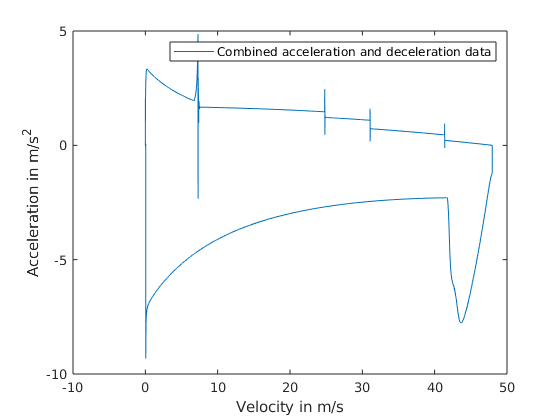

%%Load the file generated from simulink model
%%'ControllerReference_accelerationTest.slx'

load('decelerationResults.mat');
%%Read the vehicle data
vel=deceResults.VehFdbk.Body.Xdot.Data;
dece=9.81.*(deceResults.VehFdbk.Body.ax.Data);
time=deceResults.VehFdbk.Body.ax.Time;

%%plot the total data acceleration and decelerations
figure(2);
plot(vel(:,1),dece(:,1));
xlabel("Velocity in m/s")
ylabel("Acceleration in m/s^2")
legend("Combined acceleration and deceleration data")

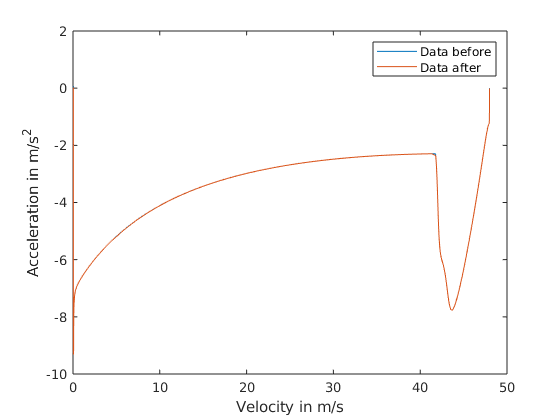


%%Exclude the acceleration data
[Max,I]=max(vel);

dece=dece(I:end);
vel=vel(I:end);
figure(3);
plot(vel,dece);
xlabel("Velocity in m/s")
ylabel("Acceleration in m/s^2")
hold on;


abs_diff=abs(diff(dece)./diff(vel));

% [ref_diff,TF]=rmoutliers(abs_diff);%,'percentile',[5 90]);

[ref_diff,TF]=rmoutliers(dece,'percentile',[0 95]);

indices=find(TF==0);
dece=dece(indices);
vel=vel(indices);

velRefined=vel;
deceRefined=dece;

diff_refined=abs(diff(deceRefined));
mean_diff=mean(diff_refined);
shiftIndices=find(diff_refined> mean_diff);

%%dividing and sampling indices between shifts indices
n=50;   %number of points in each range
finalIndices=zeros(1,n+1);
sizeSI=size(shiftIndices);
sizeSI=sizeSI(1,1);
lastIndex=size(velRefined);
lastIndex=lastIndex(1,1);

for i=1:sizeSI
    
    if i==1
        
        finalIndices=round(linspace(shiftIndices(i),shiftIndices(i+1),n));
    
    elseif i<sizeSI

        temp=round(linspace(shiftIndices(i),shiftIndices(i+1),n));
        finalIndices=[finalIndices temp];
    else
        last=round(linspace(shiftIndices(i),lastIndex,n));
        finalIndices=[finalIndices last];
        break
        
    
    end
    
end

finalIndices=unique(finalIndices);
deceFinal=deceRefined(finalIndices);
deceFinal(end)=0;
velFinal=velRefined(finalIndices);
velFinal(end)=0;

%%Arrange the data in ascending order for interpolation table
[velFinal_r, indices_r] = sortrows(velFinal);
deceFinal_r=deceFinal(indices_r);

data=[velFinal_r deceFinal_r];
%save('deceDynamicsData.mat','data');
csvwrite('inc/dynamics/vehicles/SimulinkModel/decelerationTable.csv',data);

figure(3);
plot(velFinal,deceFinal);
legend("Data before","Data after");

The filtered data is written to a *decelerationTable.csv* file which will be used during optimization.

## Generating corneringVelocityTable

The cornering velocity data is obtained by the force and moment balance during cornering. The vehicle parameters such as position of center of gravity, friction coefficient between tire and track, radius of curvature of the track affect the critical velocity.

The following script produces the curvature to cornering velocity relations.

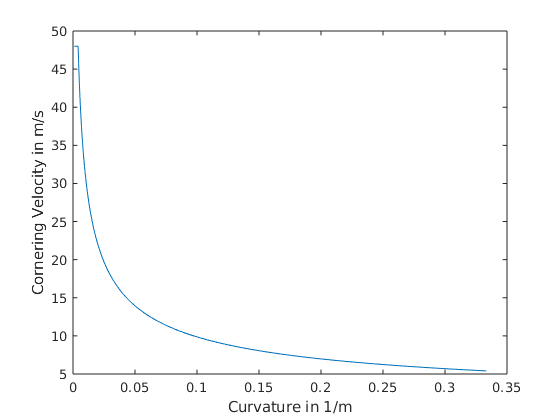

%%Defining the range of the radii for evaluating velocity-curvature
%%relations

R1 = linspace(1000,300,200);
R2 = linspace(300,3,1800);
R=[R1 R2];
curvatures=1./R;
curvatures = curvatures';
curvatures = unique(curvatures);

n=size(curvatures);
n=n(1,1);

velocities=zeros(n,1);

for i=1:n
    
    velocities(i) = criticalVelocity(curvatures(i));
end

vel_curv=[curvatures velocities];

csvwrite('inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv',vel_curv);

figure(4)
plot(curvatures(:,1),velocities(:,1));
xlabel("Curvature in 1/m")
ylabel("Cornering Velocity in m/s")